# This code is for filtering the data with random trigger and plotting the electron KE spectra


%% import the data if already converted to ANA
dir= 'E:\PhD\Adamantane_data\data\Ada_PEPICO_hv287p61eV_ke260_0001\Ada_PEPICO_hv287p61eV_ke260_0001_ana';
raw_data = IO.import_raw(dir);
mdata = md_all();
data            = macro.filter(raw_data, mdata); %define the multiplicity of events
data_corrected = macro.correct(data, mdata);

Log: Detector image translation correction performed on det1
Log: Detector image rotation correction performed on det1
Log: Radial angle-dependent correction performed on det1
Log: Detector image translation correction performed on det2
Log: Detector image rotation correction performed on det2
Log: delta TOF correction performed on det2


data_converted = macro.convert(data_corrected, mdata);

Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
Log: Background signal created for det2 on the signal(s) TOF,


## step 1 filtering for electron KE and ion TOF range

## Event statistics

e_TRG= macro.filter.write_coincidence_condition(1, 'det1'); % electron trigger
RND_TRG= macro.filter.write_coincidence_condition(0, 'det1'); % rnd trigger

[e_filter_et, ~]	= macro.filter.conditions_2_filter(data_converted,e_TRG);
data_stats.N_e = sum(e_filter_et);
[e_filter_rt, ~]	= macro.filter.conditions_2_filter(data_converted, RND_TRG);
data_stats.N_RND = sum(e_filter_rt);

%probability to detect j ions after electron trigger
for j =0:4
    etN =struct();
    etN.e_TRG= macro.filter.write_coincidence_condition(1, 'det1'); %electron trigger
    etN.ions= macro.filter.write_coincidence_condition(j, 'det2');
    [e_filter_etN, ~]	= macro.filter.conditions_2_filter(data_converted,etN);
    strg = ['etP_',num2str(j)];
    data_stats.(strg) = sum(e_filter_etN)/data_stats.N_e;
end

%probability to detect j ions after RND trigger
for j =0:4
    rtN =struct();
    rtN.RND_TRG= macro.filter.write_coincidence_condition(0, 'det1'); %RND trigger
    rtN.ions= macro.filter.write_coincidence_condition(j, 'det2');
    [e_filter_rtN, ~]	= macro.filter.conditions_2_filter(data_converted,rtN);
    strg = ['rtP_',num2str(j)];
    data_stats.(strg) = sum(e_filter_rtN)/data_stats.N_RND;
    
end

## Electron spectra

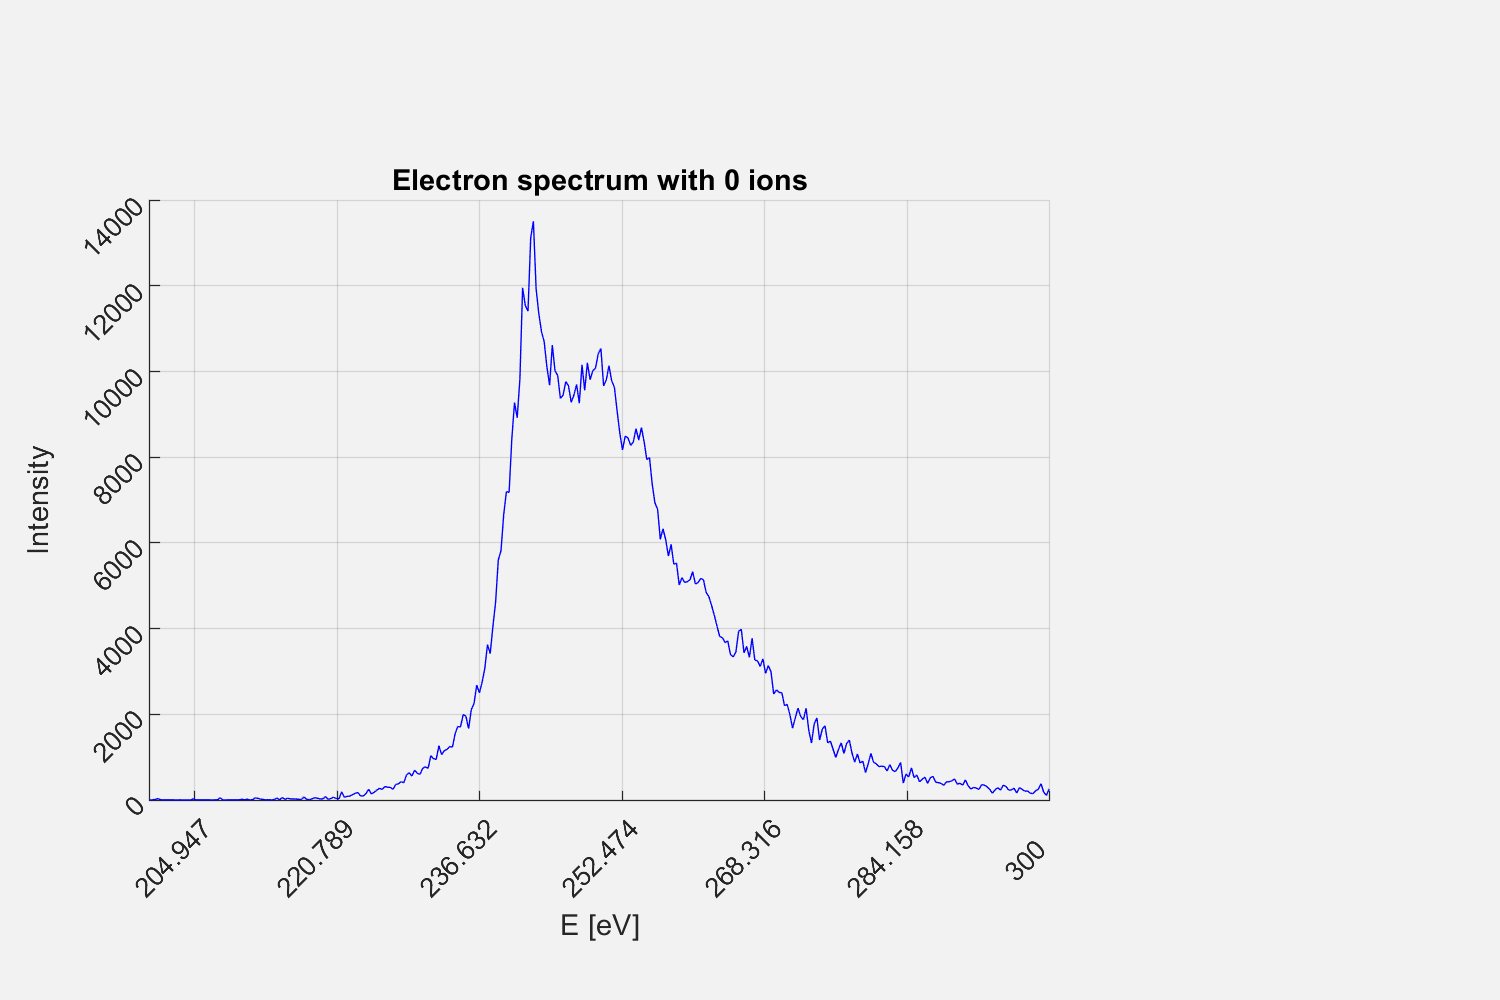

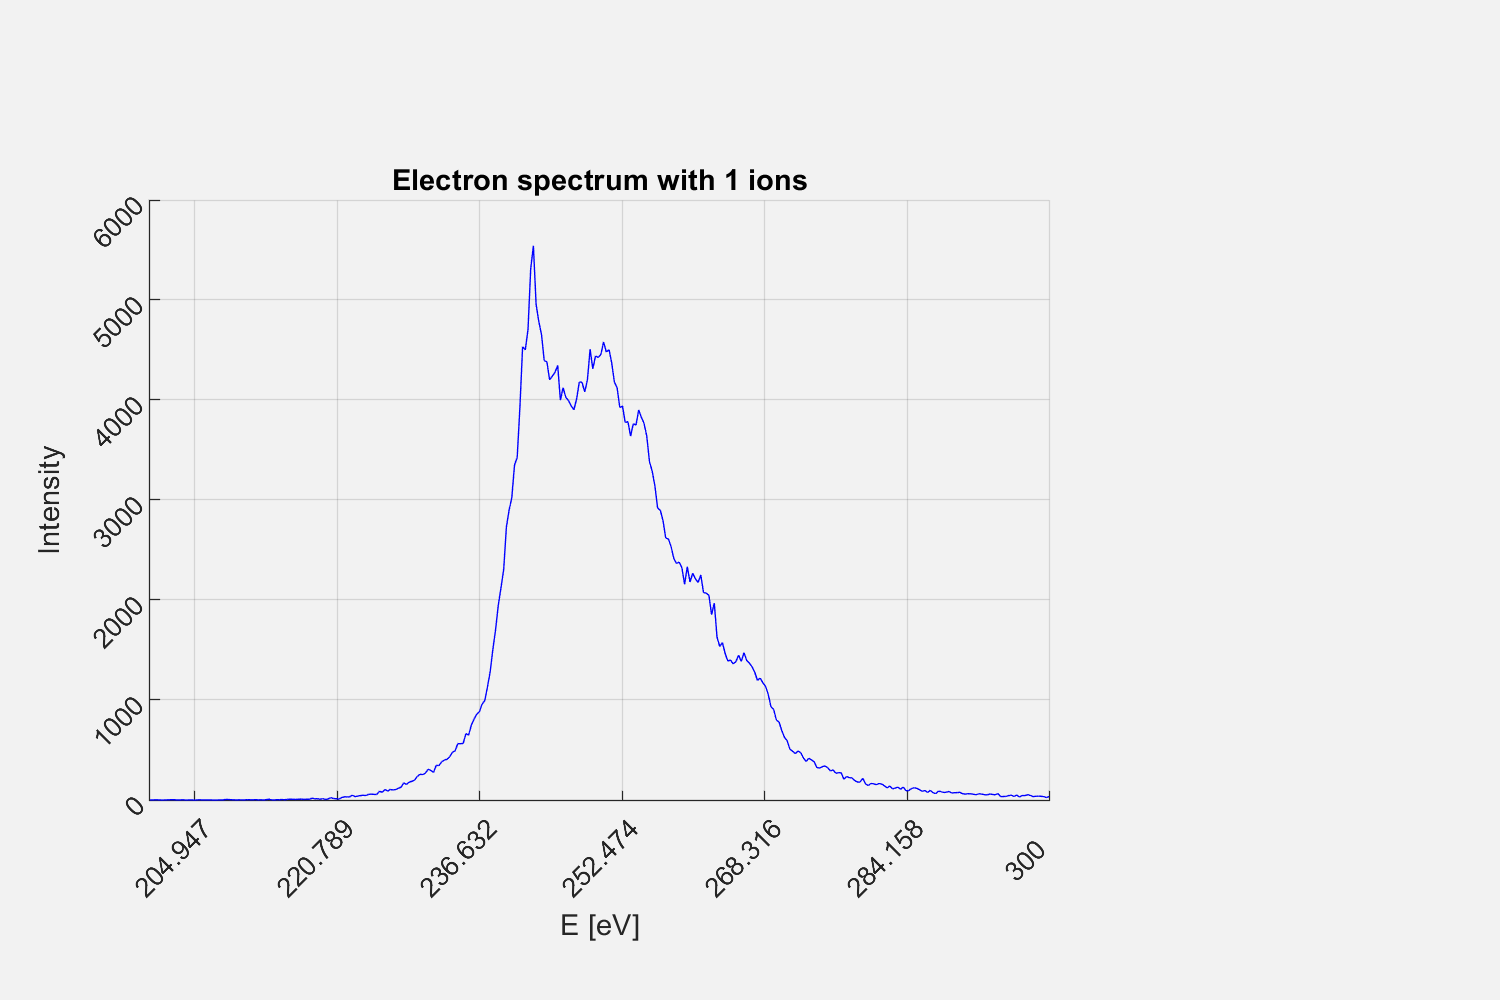

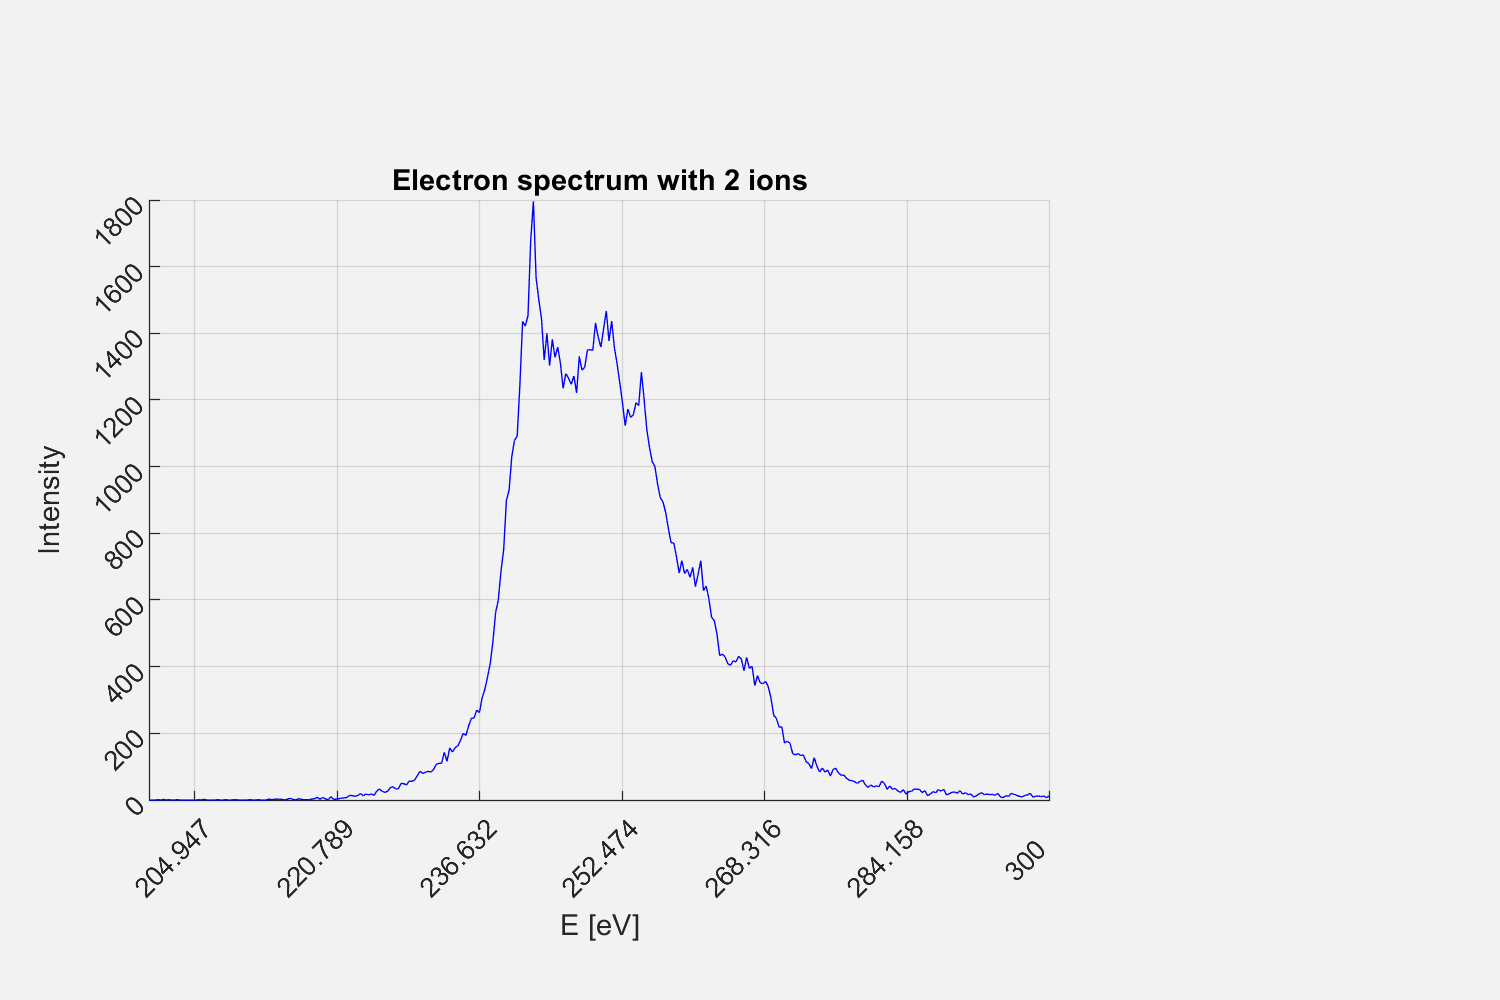

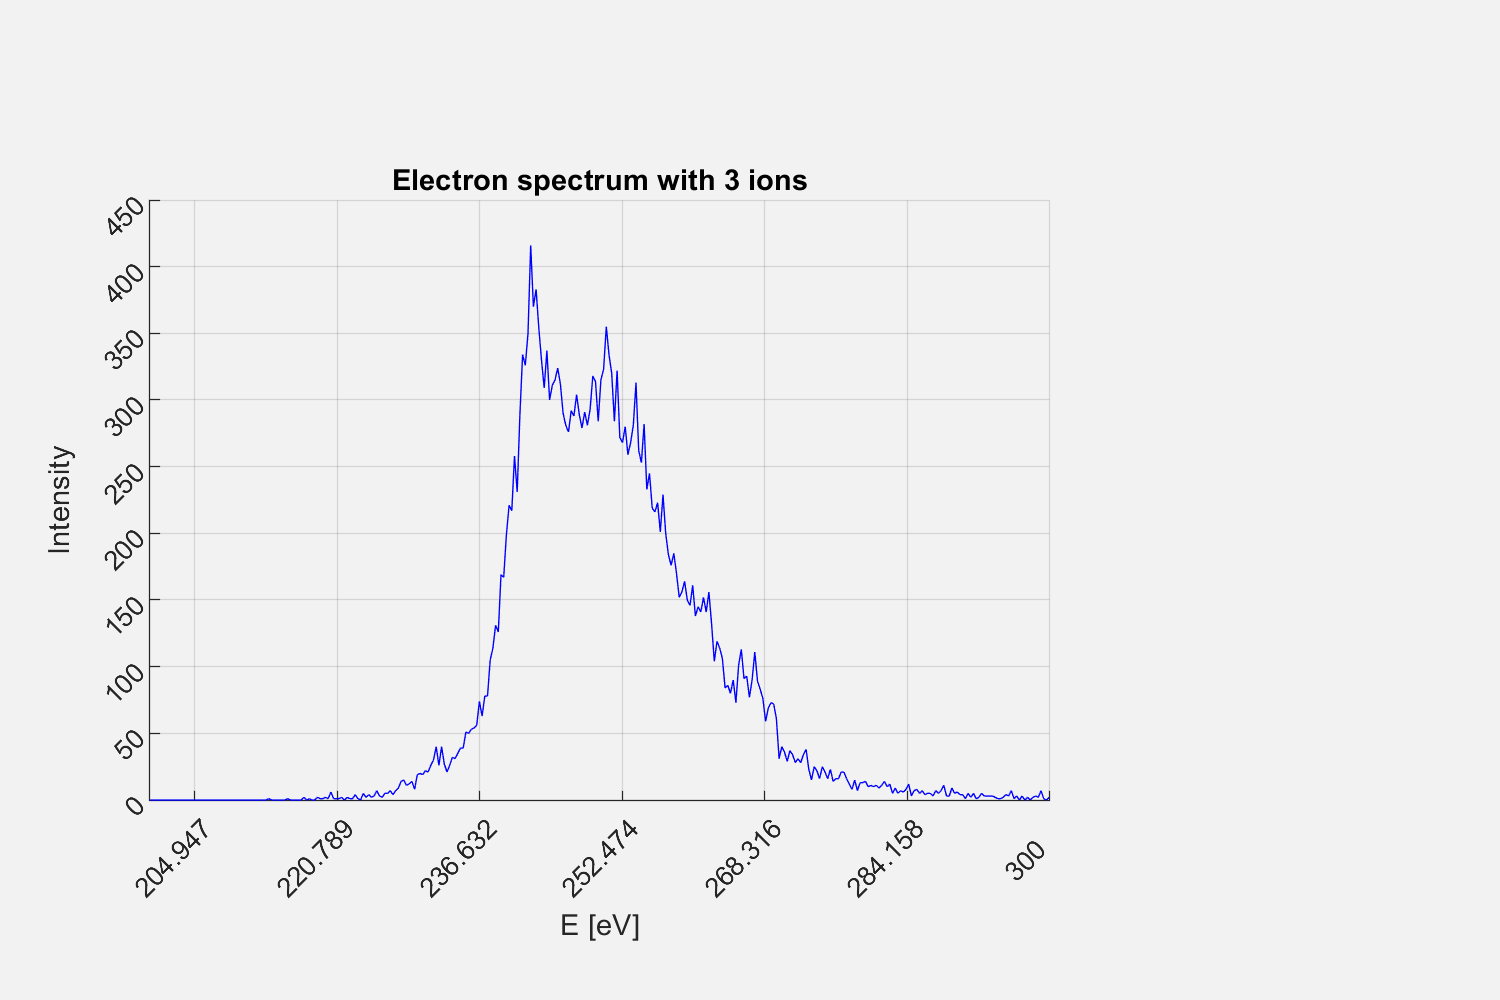

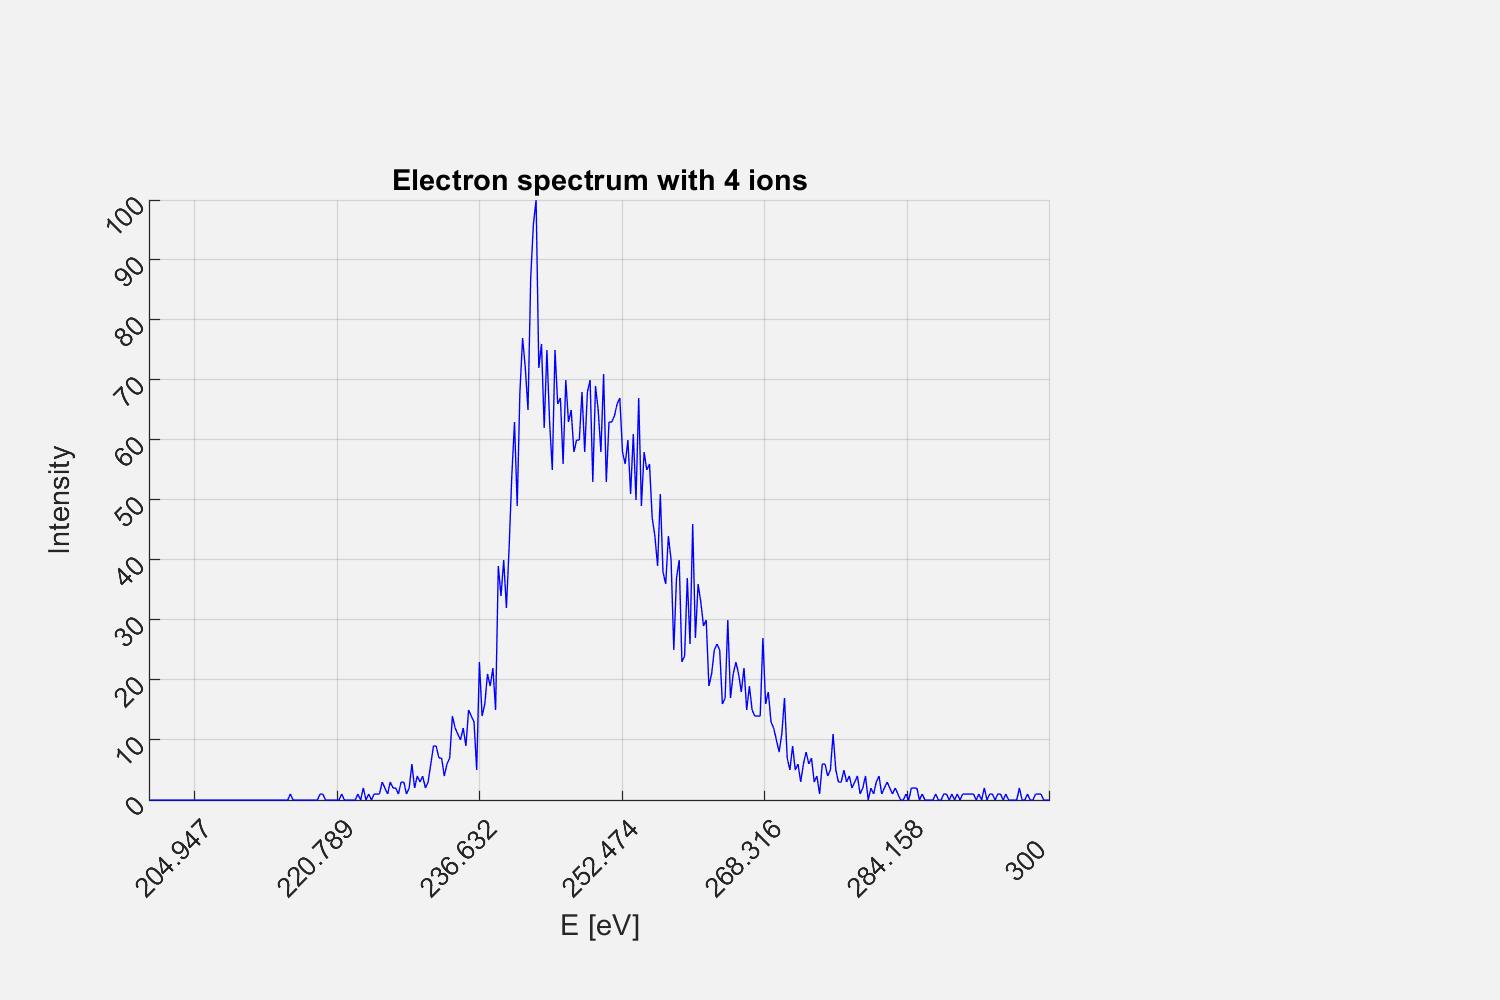

electron_KE = struct();
mdata = md_all();
mdata.plot.det1.ifdo  =struct();
mdata.plot.det1.ifdo.E =1;
% measured spectrum with j ions
for j =0:4
    mdata.plot.det1.E.cond = macro.filter.write_coincidence_condition(j, 'det2');
    strg = ['ES_',num2str(j)];
    [~, ~, ~, ~, electron_KE.(strg)]= macro.plot(data_converted, mdata);
    title(['Electron spectrum with ', num2str(j), ' ions'])
end

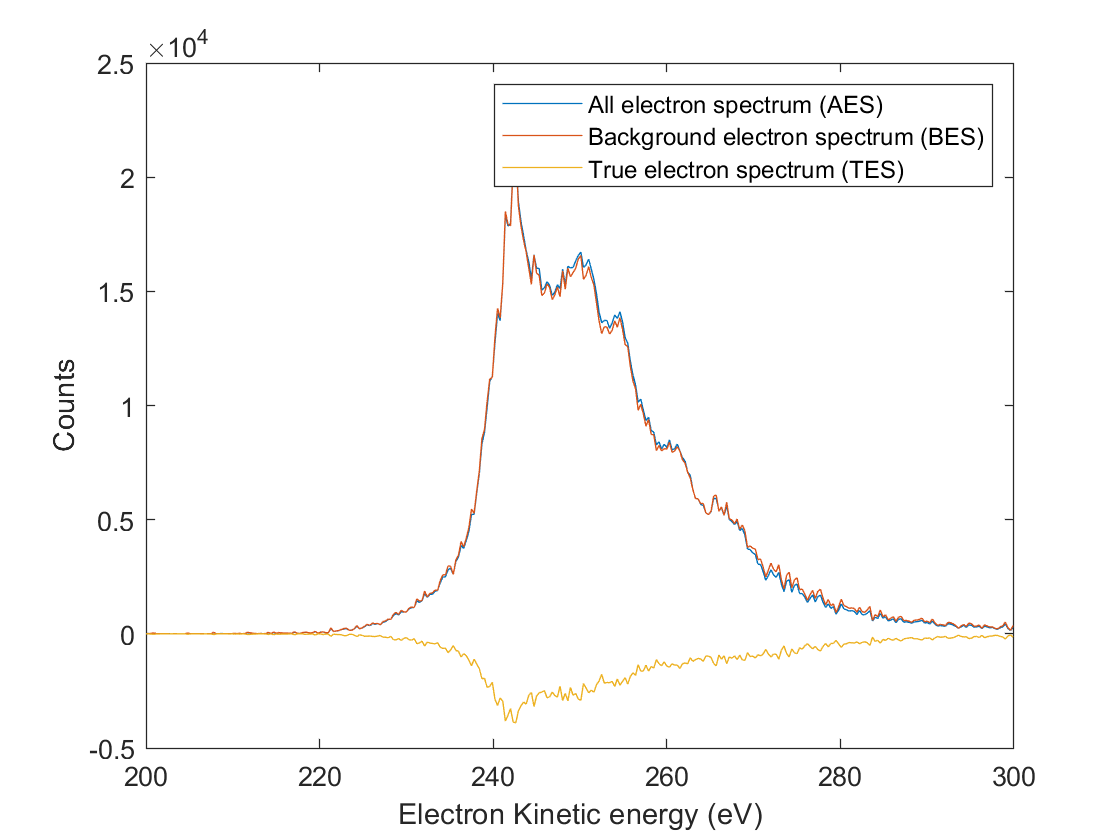


electron_KE.AES.Count = electron_KE.ES_0.Count +electron_KE.ES_1.Count+electron_KE.ES_2.Count+...
                    electron_KE.ES_3.Count+electron_KE.ES_4.Count;
figure
plot(electron_KE.ES_0.midpoints,electron_KE.AES.Count,'DisplayName','All electron spectrum (AES)')
xlabel('Electron Kinetic energy (eV)')
ylabel('Counts')
hold on

%define constants for RND backgrounds BES

c1 = data_stats.rtP_1/data_stats.rtP_0;
c2 = (data_stats.rtP_2/data_stats.rtP_0) - (data_stats.rtP_1^2/data_stats.rtP_0^2);
c3 = (data_stats.rtP_3/data_stats.rtP_0) + (data_stats.rtP_1^2/data_stats.rtP_2)...
                - 2*(data_stats.rtP_1 * data_stats.rtP_2/data_stats.rtP_0^2);

%calculate the RND backgrounds BES
electron_KE.BES_1.Count = c1 * electron_KE.ES_0.Count;
electron_KE.BES_2.Count = c2 * electron_KE.ES_0.Count + c1 * electron_KE.ES_1.Count;
electron_KE.BES_3.Count = c3 * electron_KE.ES_0.Count + c2 * electron_KE.ES_1.Count...
                          + c1 * electron_KE.ES_2.Count;

electron_KE.BES.Count = electron_KE.BES_1.Count + electron_KE.BES_2.Count +electron_KE.BES_3.Count;
plot(electron_KE.ES_0.midpoints,electron_KE.BES.Count, 'DisplayName','Background electron spectrum (BES)')


% calculates true electron spectra TES = ES - BES
electron_KE.TES_0.Count = electron_KE.ES_0.Count;
electron_KE.TES_1.Count = electron_KE.ES_1.Count - electron_KE.BES_1.Count;
electron_KE.TES_2.Count = electron_KE.ES_2.Count - electron_KE.BES_2.Count;
electron_KE.TES_3.Count = electron_KE.ES_3.Count - electron_KE.BES_3.Count;

electron_KE.TES.Count = electron_KE.TES_0.Count +electron_KE.TES_1.Count+electron_KE.TES_2.Count+...
                    electron_KE.TES_3.Count;
% figure
plot(electron_KE.ES_0.midpoints,electron_KE.TES_1.Count, 'DisplayName','True electron spectrum (TES)')
legend